% Written by Chung Yu Chan
% Load CSV and extract x and y
T = readtable('20250926_aged_Cell 5_mtDNA_ROI. 05.csv');
x = T.x;
y = T.y;

% Compute convex hull and its area
K = convhull(x, y);              % hull point indices
A_convex = polyarea(x(K), y(K)); % convex hull area

fprintf('Convex Hull Area = %.4f\n', A_convex);

Convex Hull Area = 7229.3586


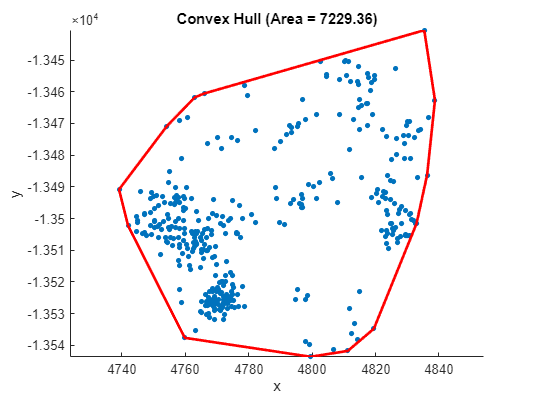

% Plot the convex hull
figure;
scatter(x, y, 15, 'filled');

hold on;
plot(x(K), y(K), 'r-', 'LineWidth', 2);
title(sprintf('Convex Hull (Area = %.2f)', A_convex));
xlabel('x'); ylabel('y');
axis equal;
hold off;